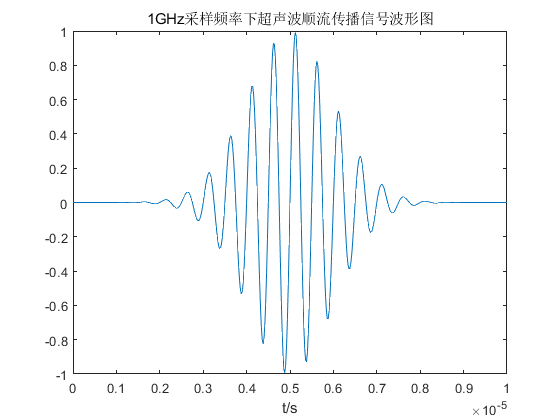

clear;
close all;
% 顺流信号
r = 1e12;
tau = 5e-6;
f = 2e6;
%fs = 1e9;
fs = 50e6;
t = 0:1/fs:2*tau;
s_12 = sin(2*pi*f .* t) .* exp(-r * (t - tau).^2 ./ 2);
figure;
plot(t,s_12);
xlim([0, 2*tau]);
xlabel('t/s');
title('1GHz采样频率下超声波顺流传播信号波形图')

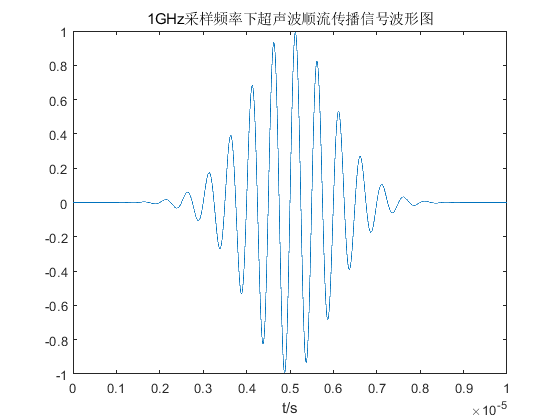

% 逆流信号
delay = [205e-9, 210e-9, 215e-9];
s21 = [];
for i = 1:3
    s = sin(2*pi*f .* (t - delay(i))) .* exp(-r * (t - delay(i) - tau).^2 ./ 2);    
    s21 = [s21;s];
end
 

% 顺流插值
%y_interp = [interp(s_12(:,1 :end-1), 1e9/50e6), s_12(:, end)];
y_interp = [interp(s_12(:,1 :end - 1), 1e9/50e6, 5, 0.4), s_12(:, end)];
figure;
t = 0:1/(1e9):2*tau;
plot(t,y_interp);
xlim([0, 2*tau]);
xlabel('t/s');
title('1GHz采样频率下超声波顺流传播信号波形图')


y_pred = [];
sigma2 = 0.5;
sigma2_s = sigma2;
alpha = 0.4;
l = 5;
for k = 1:100
    noise = randn([3, size(s_12, 2)]) * sqrt(sigma2);
    s_21gen = s21 + noise;
    s_12gen = s_12 + randn([1, size(s_12, 2)]) * sqrt(sigma2_s);
    delay_pred = [];
    s_12gen = [interp(s_12gen(:,1 :end-1), 1e9/50e6, l, alpha), s_12gen(:, end)];
    % 利用相关性测时差
    for i = 1:3
        s_21itp = [interp(s_21gen(i, 1:end-1), 1e9/50e6, l, alpha), s_21gen(i, end)];
        [r0, lags] = xcorr(s_12gen,s_21itp);
        [ytmp,ttmp] = max(r0);
        delay_pred = [delay_pred, lags(ttmp) / 1e9];
    end
    y_pred = [y_pred;delay_pred];
end
y_pred_mean = mean(y_pred, 1);
y_pred_std = std(y_pred, 1);